# MATLAB Symbolic Computation Exercise

by **(Paphatphong Painee 6670089723)**

**Problem 1** Evaluate the following limits.

(a) $\lim_{x \to \infty}  \left(1+ \frac{a}{x} \right)^x$

syms x a t
f = (1+a/x)^x;
limit(f, x, inf)

$$ans = {\mathrm{e}}^{a}$$

(b) $\lim_{x \to 0} \left(\frac{1}{x^4} \int_{0}^{x} \frac{t^3+t^4}{1+ \tan^2(\pi t^2)} \; dt \right)$

f = (t^3+t^4)/(1+(tan(pi*t^2))^2);
g = (1/x^4)*int(f,t,0,x);
limit(g,x,0)

$$ans = \frac{1}{4}$$

(c) $\lim_{t \to 0^-} \left( \int_{0}^{t} (1+x)^t \; dx \right)^{1/t}$ and $\lim_{t \to 0^+} \left( \int_{0}^{t} (1+x)^t \; dx \right)^{1/t}$

f = (1+x)^(1/t);
g = int(f,x,0,t);
limit(g,t,0,"left")

$$ans = 0$$

limit(g, t, 0, "right")

$$ans = 0$$

**Problem 2** Evaluate the following integrals.

(a) $\int \frac{1}{x^{2007}-x}\; dx$

f=(1/(x^(2007)-x));
int(f)

$$ans = \frac{\log\left(x-x^{2007}\right)}{2006}-\frac{2007\,\log\left(x\right)}{2006}$$

(b) $\int_0^1 \left(\sqrt[3]{1-x^7}-\sqrt[7]{1-x^3}\right)\; dx$  

z=(1-x^7)^(1/3)-(1-x^3)^(1/7);
int(z,x,0,1)

$$ans = 0$$

**Problem 3** Evaluate the following series.

(a) $1-\frac{1}{3}+\frac{1}{5}-\frac{1}{7}+\cdots$

syms k 
s = ((-1)^k)/(2*k+1);
symsum(s,k,0,inf)

$$ans = \frac{\pi }{4}$$

(b) $\sum_{k=1}^{\infty} \frac{1}{(k^2+1)^2}$

s=1/(k^2+1)^2;
symsum(s,k,1,inf)

$$ans = \frac{\psi (1-\mathrm{i})\,\mathrm{i}}{4}-\frac{\psi (1+\mathrm{i})\,\mathrm{i}}{4}-\frac{\psi^{\prime }(1-\mathrm{i})}{4}-\frac{\psi^{\prime }(1+\mathrm{i})}{4}$$

(c) $\sum_{k=0}^{\infty} \frac{1}{k^4+4}$

s=1/(k^4+4);
symsum(s,k,1,inf)

$$ans = \frac{1}{8}+\frac{\psi (2-\mathrm{i})\,\mathrm{i}}{8}-\frac{\psi (2+\mathrm{i})\,\mathrm{i}}{8}$$

**Problem 4** Evaluate the following limits.

(a) $\lim_{n\to\infty} \frac{1}{n}\left(\sin \frac{\pi}{n}+\sin\frac{2\pi}{n}+\cdots+\sin\frac{n\pi}{n}\right)$

syms n k
s = symsum(sin(k*pi/n),k,1,n);
limit((1/n)*s,n,inf)

$$ans = \frac{2}{\pi }$$

(b) $\lim_{n\to\infty} \frac{1}{n}\left((n+1)(n+2)\cdots(n+n)\right)^{1/n}$

s = symprod((k+n),k,1,n);
limit((1/n)*((s)^(1/n)),n,inf)

$$ans = 4\,{\mathrm{e}}^{-1}$$

**Problem 5** Solve the cubic equation $3x^3+2x^2+x -6=0$

syms x
solve(3*x^3+2*x^2+x-6==0)

$$ans = \left(\begin{array}{c} 1\\ -\frac{5}{6}-\frac{\sqrt{47}\,\mathrm{i}}{6}\\ -\frac{5}{6}+\frac{\sqrt{47}\,\mathrm{i}}{6} \end{array}\right)$$

**Problem 6**  Plot the polar curve  $r=\sin \theta + \sin^3 \frac{5\theta}{2}$ where $0 \le \theta \le 4\pi$

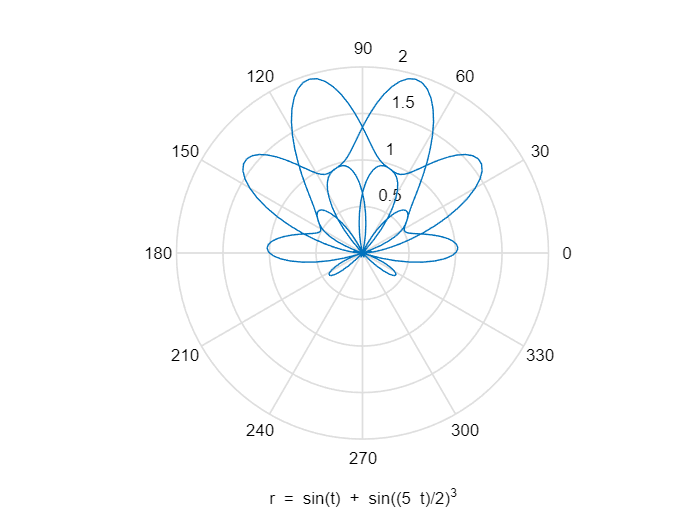

syms t
ezpolar(sin(t)+(sin(5*t/2))^3,[0,4*pi])

**Problem 7**  Create a three-dimentional plot for  $z=\sin y\cos x$  where $0 \le x \le 4\pi$ and $0 \le y \le 4\pi$.

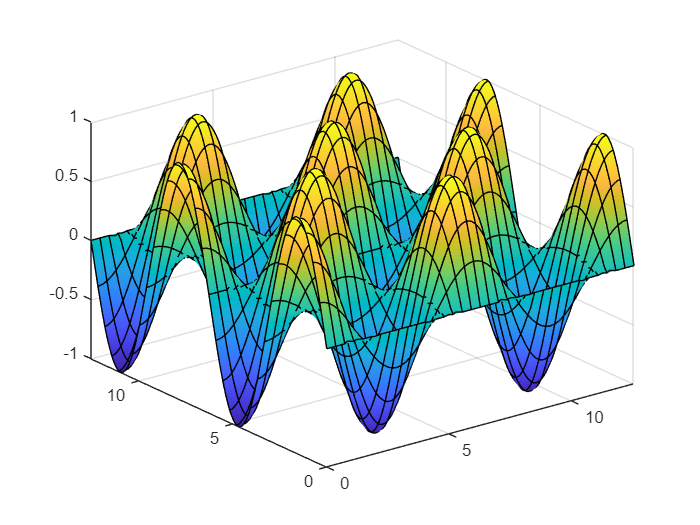

syms x y
fsurf(sin(y)*cos(x),[0 4*pi 0 4*pi])

Create  a countour plot for  $z=\sin y\cos x$  where $0 \le x \le 4\pi$ and $0 \le y \le 4\pi$.

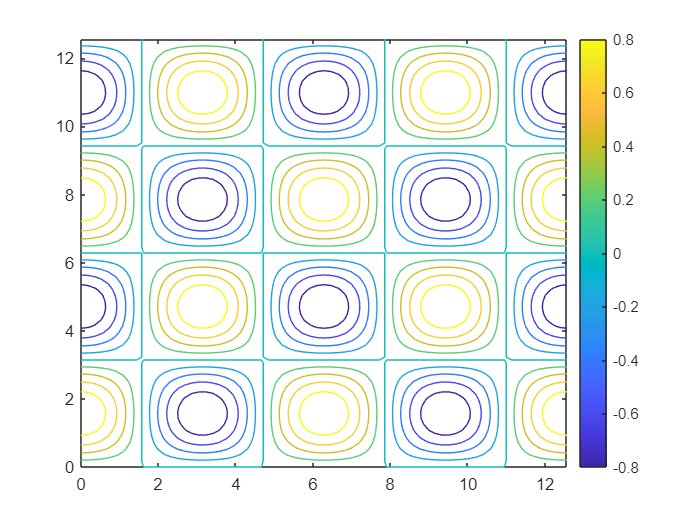

syms x y
fcontour(sin(y)*cos(x),[0 4*pi 0 4*pi])
colorbar